# Schroedinger Eigenmaps Algorithm Walkthrough

This is a sample script for the Schroedinger Eigenmaps algorithm. I am going to walk through and deconstruct the original script found [here](http://www.mathworks.com/matlabcentral/fileexchange/45908-spatial-spectral-schroedinger-eigenmaps) piece-by-piece.

Indian Pines Data Available from:

- [IndianPines Corrected Image](http://www.ehu.es/ccwintco/uploads/6/67/Indian_pines_corrected.mat)

- [Indian Pines Ground Truth](http://www.ehu.es/ccwintco/uploads/6/67/Indian_pines_gt.mat)

% Priminary stuff
clear all; close all; clc;

## Load Indian Pines Data

% add file path of where my data is located
addpath('H:\Data\Images\RS\IndianPines')
% addpath('/media/eman/Emans HDD/Data/Images/RS/IndianPines')

% load the images
load('Indian_pines_corrected.mat');
load('Indian_pines_gt.mat');

% set them to variables
img = indian_pines_corrected;
gt = indian_pines_gt;

% clear the path as well as the datafiles 
clear indian*
addpath('H:\Data\Images\RS\IndianPines')
% rmpath('/media/eman/Emans HDD/Data/Images/RS/IndianPines')

%##########################################

## Reorder and Rescale data into a 2D array

%##########################################
%{
    We do this in order to make the data more workable as well as rescale
    the data to the unit norm. We can't do processing as is with the 
    3D cube. So we make a 2D cube where it's basically a long vector
    of values with features representative as each dimension.
%}

% get the dimensions of the image
[dims.rows, dims.cols, dims.spectra] = size(img);

% find the squared values along the 3rd dimension of the array
scfact = sum(img.^2,3);

% reshape the summation into an image vector (rows*cols x dims)
scfact = reshape(scfact, dims.rows*dims.cols, 1);


The max of the image is: 5.02e-06.


% take the mean of that 

The min of the image is: 4.99e-07.


scfact = mean(scfact);

% divide the entire image by that mean
img = img./scfact;

fprintf('The max of the image is: %.2d.\n', max(img(:)))
fprintf('The min of the image is: %.2d.\n', min(img(:)))

% create the image vector
imgVec = reshape(img, [dims.rows*dims.cols dims.spectra]);
gt_Vec = reshape(gt, [dims.rows*dims.cols 1]);
dims.nodes = size(imgVec,1);

%##########################################

## k-NN Distance Function

This is the section where we would like to find the k-neareste neighbors for our (N x D) data points.

Since this takes quite a bit of time, I like to save the KNN search for future implementations because the literature suggest that the k parameter doesn't have a huge effect on the outcome of the results.

%#########################################

% K NEAREST NEIGHBORS
knnVal = 20;
distType = 'euclidean';     % distance measure between neighbors


try
    % try loading in previous data in subdirectory
    load('saved_data/se_knn_data');
    disp('Found previous computation in saved files...');
catch
    
    % if not, will manually do implementation and save it for later
    warning('No previous implementations...calculating knn...could take a while...');
    
    % first, find the 20-nearest neighbors
    
    %-------------------------------------
    % MATLAB Implementation - KDTree Method
    tic;
    
    % initialize the KD Tree Model
    KDModel = KDTreeSearcher(imgVec, 'Distance', distType);
    
    % query the vector for k nearest neighbors
    [knn.idxkd, knn.distkd]=knnsearch(KDModel, imgVec,'k',...
        knnVal+1);
    knn.timekd = toc;
    
    % print time elapsed
    fprintf('KD Tree Search - MATLAB: %.3f.s\n', knn.timekd)
    
    knn.idxkd = knn.idxkd(:, 2:end);
    knn.distkd = knn.distkd(:, 2:end);    
    %-------------------------------------
    % MATLAB Implementation - Brute force
    tic;
    [knn.idx, knn.dist]=knnsearch(imgVec, imgVec,'k',...
        knnVal+1,'Distance',distType);
    knn.time = toc;
    
    % print time elapsed
    fprintf('Knn Search - MATLAB: %.3f.s\n', knn.time)
    
    knn.idx = knn.idx(:, 2:end);
    knn.dist = knn.dist(:, 2:end);
    
    % save knn implementations for later
    disp('...saving knn data for later usage...');

Found previous computation in saved files...


    save('saved_data/se_knn_data.mat', 'knn')
end


## Distance Kernels

This is where we define the weights between the pairwise components. And in all honesty this is really the only part where most kernel eigenmap methods (or output normalized methods) are really different; it's simply a matter of finding appropriate kernels to describe the data effectively that heavily depends on your data and situation.


% element-wise operation 
% 1) pairwise distances squared
% 2) - sol/sigma_parameter
% 3) exponentiate

kernel = 'heat';

tic;
switch kernel
    case 'heat'
        w = exp(-(knn.dist.^2)./(.5.^2));
    case 'cosine'
        w = exp(-acos(1-knn.dist));
end
time = toc;

% print time elapsed
fprintf('Kernelized distVals: %.3f.s\n', time)

Kernelized distVals: 0.033.s


## Create Spectral Adjacency Matrix

This is where we create the adjacency matrix. The function to use is the 

**sparse(i,j,v,m,n) **where

- i is the x-coordinate

- j is the y-coordinate

- v is the entry

- m, n is the (m x n) size of the matrix

The variables in this case represent

- i : repeat the length of nodes for the graph from 1 to k

- j : insert the knn indices found

- v : insert the knn weighted distances found

- m , n : number of nodes in the graph (n samples from data)

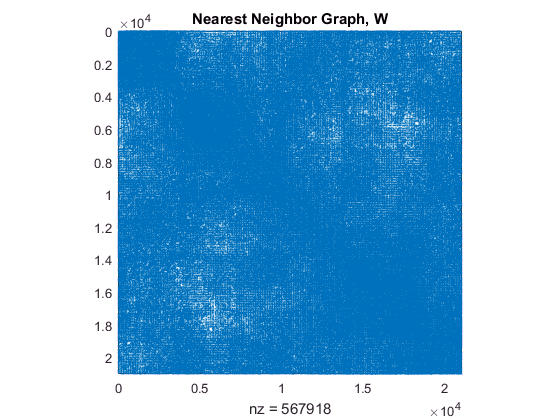

% assign the variables
i = repmat((1:dims.nodes)',[1 knnVal]);
j = knn.idx;
v = w;
[m, n] = deal(dims.nodes);

% create the spare matrix
W = sparse(i,j,v, m, n);

% make the matrix symmetric by taking the max
W = max(W,W');      

% take a peek at what the graph looks like
figure(1);
spy(W, 1e-16)
title('Nearest Neighbor Graph, W');


%#########################################

## Construct Graph Laplacian

**spdiags(B,d,m,n) **where:

- B is a vector of elements

- d is the place within the diagonal range (0 is the exact diagonal)

- m, n is the (m x n) size of the matrix

The variables in this case represent:

- B : sum the W matrix along the columns

- d : 0 (we want it in the center)

- m , n : number of samples of imgVec

%#########################################

% Diagonal Degree Matrix
D = spdiags(sum(W, 2), 0, dims.nodes, dims.nodes);

% SPECTRAL LAPLACIAN MATRIX (D-W)
L = D - W;

%############################################

## Laplacian Eigenmaps Embedding

At this point we are basically done and can simply use a graph embedding method to find the smallest d eigenvalues and their associated eigenvectors.

## SchroedingerEigenmaps Spatial Data

This will stem from the data acquired from the imageas we are basically only taking into account the 2-D array. So the set up is to create a vector that simulates 

Create a meshgrid function that will be the size of the spatial domain of the image. the meshgrid function basically captures the coordinates of the image.

[x, y] = meshgrid(1:dims.cols, 1:dims.rows);

Now that we have the coordinates, create a matrix that has coordinates laid out side by side like an imgVec. think of it like a long vector with 2 features: the x-direction and y-direction.

pData = [x(:) y(:)];

fprintf('Size of pData vector:')

Size of pData vector:

size(pData)

ans =        21025           2



fprintf('A peek at the first few values:')

A peek at the first few values:

pData(1:5,:)

ans =      1     1
     1     2
     1     3
     1     4
     1     5



fprintf('A peek at the last few values:')

A peek at the last few values:

pData(21020:end,:)

ans =    145   140
   145   141
   145   142
   145   143
   145   144
   145   145


As you can see, the first column represents the x-cordinate and the second column represents the y-coordinate from the original image. So by doing a k-nn search, we are essentially comparing the spatial neighbours only.

Example, just from here, the 4 nearest neighbor for the first x-coordinate would be the y-coordinates 1,2,3,4. Which is pretty obvious as you can imagine that is simply the corner of our image.

## Spatial Adjacency Matrix

We constuct the adjacency matrix in the same manner as the spectral adjacency matrix.

1. Find the **k-nearest neighbors**. I like to choose 4 but one could choose however many they would like to.

%#########################################

% spatial k-nearest neighbors
knnVal = 4;
distType = 'euclidean';     % distance measure between spatial neighbors
saved_file = 1;

try
    % try loading in previous data in subdirectory
    load('saved_data/sesp_knn_data');
    disp('Found previous computation in saved files...');
catch
    
    % if not, will manually do implementation and save it for later
    warning('No previous implementations...calculating knn...');
    disp('Will be much faster than spatial neighbors..');
    
    % first, find the 20-nearest neighbors
    
    %-------------------------------------
    % MATLAB Implementation - KDTree Method
    tic;
    
    % initialize the KD Tree Model
    KDModel = KDTreeSearcher(pData, 'Distance', distType);
    
    % query the vector for k nearest neighbors
    [knn.idxkdsp, knn.distkdsp]=knnsearch(KDModel, pData,'k',...
        knnVal+1);
    knn.timekd = toc;
    
    % print time elapsed
    fprintf('KD Tree Search - MATLAB: %.3f.s\n', knn.timekd)
    
    knn.idxkdsp = knn.idxkdsp(:, 2:end);
    knn.distkdsp = knn.distkdsp(:, 2:end);    
    %-------------------------------------
    % MATLAB Implementation - Brute force
    tic;
    [knn.idxsp, knn.distsp]=knnsearch(pData, pData,'k',...
        knnVal+1,'Distance',distType);
    knn.time = toc;
    
    % print time elapsed
    fprintf('Knn Search - MATLAB: %.3f.s\n', knn.time)
    
    knn.idxsp = knn.idxsp(:, 2:end);
    knn.distsp = knn.distsp(:, 2:end);
    
    % save knn implementations for later
    disp('...saving knn data for later usage...');
    save('saved_data/sesp_knn_data.mat', 'knn')
end

Found previous computation in saved files...


2. Produce a **kernel **to define the distances between the points. To be different, let's use the cosine angle formula.

kernel = 'cosine';

tic;
switch kernel
    case 'heat'
        wsp = exp(-(knn.distsp.^2)./(.5.^2));
    case 'cosine'
        wsp = exp(-acos(1-knn.distsp));
end
time = toc;

% print time elapsed
fprintf('Kernelized spatial distVals: %.3f.s\n', time)

Kernelized spatial distVals: 0.021.s


3. Construct the **spatial adjacency matrix**.

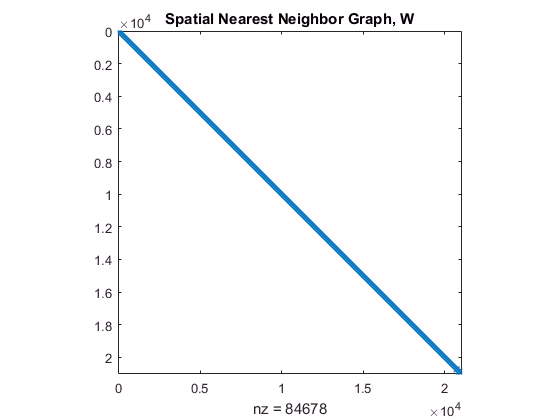

% assign the variables
i = repmat((1:dims.nodes)',[1 knnVal]);
j = knn.idxsp;
v = wsp;
[m, n] = deal(dims.nodes);


% create the spare matrix
Wsp = sparse(i,j,v, m, n);

% make the matrix symmetric by taking the max
Wsp = max(Wsp,Wsp');      

% take a peek at what the graph looks like
figure(1);
spy(Wsp, 1e-16)
title('Spatial Nearest Neighbor Graph, W');

## Schroedinger Spatial-Spectral Potential

At this point, this is where things start to get tricky. The formula we would like to emulate is:


$$\mathbf{V_{ss}=\sum_{i}^k\sum_{x_j \in \mathcal{N}_\epsilon^p(x_i)}\gamma_{i,j}W_{i,j}exp \left( -\frac{||x_i^p=x_j^p||^2}{\sigma^2_p}\right)}$$


## Eigenvalue Decomposition

%############################################
try 
    
    % try loading in previous data in subdirectory
    load('saved_data/le_eigvals');
    disp('Found previous computation in saved files...');
catch
    n_components = 150;
    options.n_components = n_components;
    
    tic;
    [embedding, lambda] = LaplacianEigenmaps(W, options);
    time = toc;
    
    % number of components we want to keep


    tic;

    fprintf('Eigenvalue Decomposition: %.3f.\n', time)
    save('saved_data/le_eigvals.mat', 'embedding', 'lambda')
end